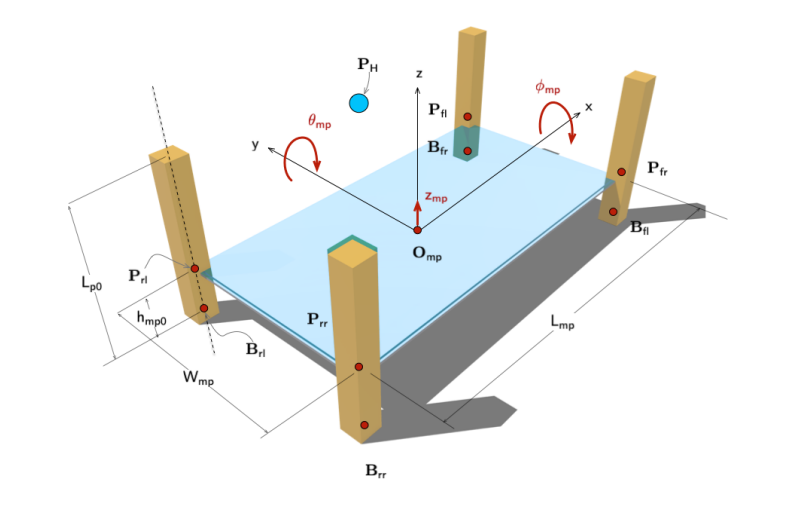

define the parameter  NB: the measure are in m

clear
clc
Lmp = 1.6;
Wmp = 0.82;
addpath('MBsLib_v2/')

define the ground frame

TG=ground();
P0 = get_origin(TG);

define translation matrix from ground to one frame on a base actuactor (Brr) and the translation matrix to the other bases  i let three point free to moved

x_rr = -Lmp/2;
y_rr = -Wmp/2;
syms x_fr y_fr x_fl y_fl x_rl y_rl

TBrr = translate([x_rr y_rr 0]);
TBfr = translate([x_fr y_fr 0]);
TBfl = translate([x_fl y_fl 0 ]);
TBrl = translate([x_rl y_rl 0]);


Brr= project(subtract(P0, get_origin(TBrr)), TG).coords;
Brl= project(subtract(P0, get_origin(TBrl)), TG).coords;
Bfr= project(subtract(P0, get_origin(TBfr)), TG).coords;
Bfl= project(subtract(P0, get_origin(TBfl)), TG).coords;

define transformation matrix from ground to center of mass of the platform

syms x_mp y_mp z_mp phi_mp theta_mp
Tmp = translate([x_mp y_mp z_mp]) * rotate('X',phi_mp) * rotate('Y', theta_mp);
disp(Tmp)

$$\left(\begin{array}{cccc} \cos\left(\theta_{\mathrm{mp}}\right) & 0 & \sin\left(\theta_{\mathrm{mp}}\right) & x_{\mathrm{mp}}\\ \sin\left(\varphi_{\mathrm{mp}}\right)\,\sin\left(\theta_{\mathrm{mp}}\right) & \cos\left(\varphi_{\mathrm{mp}}\right) & -\cos\left(\theta_{\mathrm{mp}}\right)\,\sin\left(\varphi_{\mathrm{mp}}\right) & y_{\mathrm{mp}}\\ -\cos\left(\varphi_{\mathrm{mp}}\right)\,\sin\left(\theta_{\mathrm{mp}}\right) & \sin\left(\varphi_{\mathrm{mp}}\right) & \cos\left(\varphi_{\mathrm{mp}}\right)\,\cos\left(\theta_{\mathrm{mp}}\right) & z_{\mathrm{mp}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% i define the matrix with only rotations. Needed to define the rigid arm vectors on the top of the platform
Tmp_rotation =rotate('X',phi_mp) * rotate('Y', theta_mp);

I simplify for small angles.

Tmp=subs(Tmp,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
Tmp_rotation=subs(Tmp_rotation,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
disp(Tmp);

$$\left(\begin{array}{cccc} 1 & 0 & \theta_{\mathrm{mp}} & x_{\mathrm{mp}}\\ \varphi_{\mathrm{mp}}\,\theta_{\mathrm{mp}} & 1 & -\varphi_{\mathrm{mp}} & y_{\mathrm{mp}}\\ -\theta_{\mathrm{mp}} & \varphi_{\mathrm{mp}} & 1 & z_{\mathrm{mp}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

define transformation matrix from center of mass of the platform to the edges of the platform ( in local coordinates).

TPrl = translate([-Lmp/2 Wmp/2 0]);
TPrr = translate([-Lmp/2 -Wmp/2 0]);
TPfl = translate([Lmp/2 Wmp/2 0]);
TPfr = translate([Lmp/2 -Wmp/2 0]);


Prl = Tmp_rotation*TPrl;
Prr = Tmp_rotation*TPrr;
Pfl = Tmp_rotation*TPfl;
Pfr = Tmp_rotation*TPfr;


Pcm= project(subtract(P0, get_origin(Tmp)), TG).coords;
Prl= project(subtract(P0, get_origin(Prl)), TG).coords;
Prr= project(subtract(P0, get_origin(Prr)), TG).coords;
Pfl= project(subtract(P0, get_origin(Pfl)), TG).coords;
Pfr= project(subtract(P0, get_origin(Pfr)), TG).coords;


define transformation from the base actuator to actuators top (NB: it's a prismatic joint but the reference system in the top actuator is not parrallel to the one in the base,  it need to be parallel to the one in the platform refernce system , so it's subject to the same rotations of that one)

syms hmp_rr hmp_rl hmp_fl hmp_fr
THp_rr =  rotate('X',phi_mp) * rotate('Y', theta_mp) *translate([0 0 hmp_rr]);
THp_rl =  rotate('X',phi_mp) * rotate('Y', theta_mp)*translate([0 0 hmp_rl]);
THp_fl =  rotate('X',phi_mp) * rotate('Y', theta_mp)*translate([0 0 hmp_fl]);
THp_fr =  rotate('X',phi_mp) * rotate('Y', theta_mp)*translate([0 0 hmp_fr]);

disp(THp_fr);

$$\left(\begin{array}{cccc} \cos\left(\theta_{\mathrm{mp}}\right) & 0 & \sin\left(\theta_{\mathrm{mp}}\right) & {\mathrm{hmp}}_{\mathrm{fr}}\,\sin\left(\theta_{\mathrm{mp}}\right)\\ \sin\left(\varphi_{\mathrm{mp}}\right)\,\sin\left(\theta_{\mathrm{mp}}\right) & \cos\left(\varphi_{\mathrm{mp}}\right) & -\cos\left(\theta_{\mathrm{mp}}\right)\,\sin\left(\varphi_{\mathrm{mp}}\right) & -{\mathrm{hmp}}_{\mathrm{fr}}\,\cos\left(\theta_{\mathrm{mp}}\right)\,\sin\left(\varphi_{\mathrm{mp}}\right)\\ -\cos\left(\varphi_{\mathrm{mp}}\right)\,\sin\left(\theta_{\mathrm{mp}}\right) & \sin\left(\varphi_{\mathrm{mp}}\right) & \cos\left(\varphi_{\mathrm{mp}}\right)\,\cos\left(\theta_{\mathrm{mp}}\right) & {\mathrm{hmp}}_{\mathrm{fr}}\,\cos\left(\varphi_{\mathrm{mp}}\right)\,\cos\left(\theta_{\mathrm{mp}}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

then i simplify them for small angles

THp_rr=subs(THp_rr,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
THp_rl=subs(THp_rl,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
THp_fl=subs(THp_fl,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});
THp_fr=subs(THp_fr,{cos(theta_mp),cos(phi_mp),sin(theta_mp),sin(phi_mp)},{1,1,theta_mp,phi_mp});

disp(THp_fr);

$$\left(\begin{array}{cccc} 1 & 0 & \theta_{\mathrm{mp}} & {\mathrm{hmp}}_{\mathrm{fr}}\,\theta_{\mathrm{mp}}\\ \varphi_{\mathrm{mp}}\,\theta_{\mathrm{mp}} & 1 & -\varphi_{\mathrm{mp}} & -{\mathrm{hmp}}_{\mathrm{fr}}\,\varphi_{\mathrm{mp}}\\ -\theta_{\mathrm{mp}} & \varphi_{\mathrm{mp}} & 1 & {\mathrm{hmp}}_{\mathrm{fr}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


Hp_rr= project(subtract(P0, get_origin(THp_rr)), TG).coords;
Hp_rl= project(subtract(P0, get_origin(THp_rl)), TG).coords;
Hp_fr= project(subtract(P0, get_origin(THp_fr)), TG).coords;
Hp_fl= project(subtract(P0, get_origin(THp_fl)), TG).coords;

## **Direct Kinematics**

hrr = 1.01;
hrl = 1.0062145;
hfl = 1.008374723;

we create  the equations to find x_mp y_mp z_mp phi_mp theta_mp based on the loops

i can use two approaches : or with matrices or with the T-graph, both returning the same result

eq_rr = Brr + Hp_rr -Prr - Pcm == 0;
eq_rl = Brl + Hp_rl -Prl - Pcm == 0;
eq_fl = Bfl + Hp_fl -Pfl - Pcm == 0;
eq_fr = Bfr + Hp_fr -Pfr - Pcm == 0;


eqs = [eq_rr(1:3);eq_fl(1:3);eq_fr(1:3);eq_rl(1:3)];
sol_sym = solve(eqs, [hmp_rr x_mp y_mp z_mp phi_mp theta_mp x_fr y_fr x_fl y_fl x_rl y_rl]);
disp(sol_sym);

      hmp_rr: hmp_fr - hmp_fl + hmp_rl
        x_mp: (5*hmp_fl^2)/8 - (5*hmp_fl*hmp_rl)/4 - (5*hmp_fr*hmp_fl)/8 + (5*hmp_rl^2)/8 + (5*hmp_fr*hmp_rl)/8
        y_mp: (25*hmp_fl^2)/41 - (75*hmp_fl*hmp_fr)/41 - (25*hmp_rl*hmp_fl)/41 + (50*hmp_fr^2)/41 + (25*hmp_rl*hmp_fr)/41
        z_mp: hmp_fr/2 + hmp_rl/2
      phi_mp: (50*hmp_fl)/41 - (50*hmp_fr)/41
    theta_mp: (5*hmp_rl)/8 - (5*hmp_fl)/8
        x_fr: (5*hmp_fl^2)/8 - (5*hmp_fl*hmp_rl)/4 + (5*hmp_rl^2)/8 + 4/5
        y_fr: -41/100
        x_fl: (5*hmp_fl^2)/4 - (15*hmp_fl*hmp_rl)/8 - (5*hmp_fr*hmp_fl)/8 + (5*hmp_rl^2)/8 + (5*hmp_fr*hmp_rl)/8 + 4/5
        y_fl: (50*hmp_fl^2)/41 - (100*hmp_fl*hmp_fr)/41 + (50*hmp_fr^2)/41 + 41/100
        x_rl: (5*hmp_fr*hmp_rl)/8 - (5*hmp_fl*hmp_rl)/8 - (5*hmp_fl*hmp_fr)/8 + (5*hmp_fl^2)/8 - 4/5
        y_rl: (50*hmp_fl^2)/41 - (100*hmp_fl*hmp_fr)/41 + (50*hmp_fr^2)/41 + 41/100




z_sol= sol_sym.z_mp;
phi_sol= sol_sym.phi_mp;
thetha_sol = sol_sym.theta_mp;
h_sol=sol_sym.hmp_rr;

the angular equations are already verified by definition becouse the joint are subjects to the same rotations as the plane.

eqs_sub = subs(eqs, [hmp_rr hmp_rl hmp_fl], [hrr hrl hfl]);
sol = solve(eqs_sub, [hmp_fr x_mp y_mp z_mp phi_mp theta_mp x_fr y_fr x_fl y_fl x_rl y_rl]);

P_top = zeros(4,3);

THp_rr_sub = subs(THp_rr, {theta_mp, phi_mp, hmp_rr}, {sol.theta_mp, sol.phi_mp, double(sol.hmp_fr)});

tmp = THp_rr_sub * [double(x_rr); double(y_rr); 0; 1];
P_top(1, :) = tmp(1:3)';

THp_rl_sub = subs(THp_rl, {theta_mp, phi_mp, hmp_rl}, {sol.theta_mp, sol.phi_mp, double(sol.hmp_fr)});

tmp = THp_rl_sub * [double(sol.x_rl); double(sol.y_rl); 0; 1];
P_top(2, :) = tmp(1:3)';

THp_fl_sub = subs(THp_fl, {theta_mp, phi_mp, hmp_fl}, {sol.theta_mp, sol.phi_mp, double(sol.hmp_fr)});

tmp = THp_fl_sub * [double(sol.x_fl); double(sol.y_fl); 0; 1];
P_top(3, :) = tmp(1:3)';

THp_fr_sub = subs(THp_fr, {theta_mp, phi_mp, hmp_fr}, {sol.theta_mp, sol.phi_mp, double(sol.hmp_fr)});

tmp = THp_fr_sub * [double(sol.x_fr); double(sol.y_fr); 0; 1];
P_top(4, :) = tmp(1:3)';

P_base = zeros(4,3);

P_base(1, :) = [x_rr, y_rr, 0];

P_base(2, :) = [double(sol.x_rl), double(sol.y_rl), 0];

P_base(3, :) = [double(sol.x_fl), double(sol.y_fl), 0];

P_base(4, :) = [double(sol.x_fr), double(sol.y_fr), 0];

## Plotting

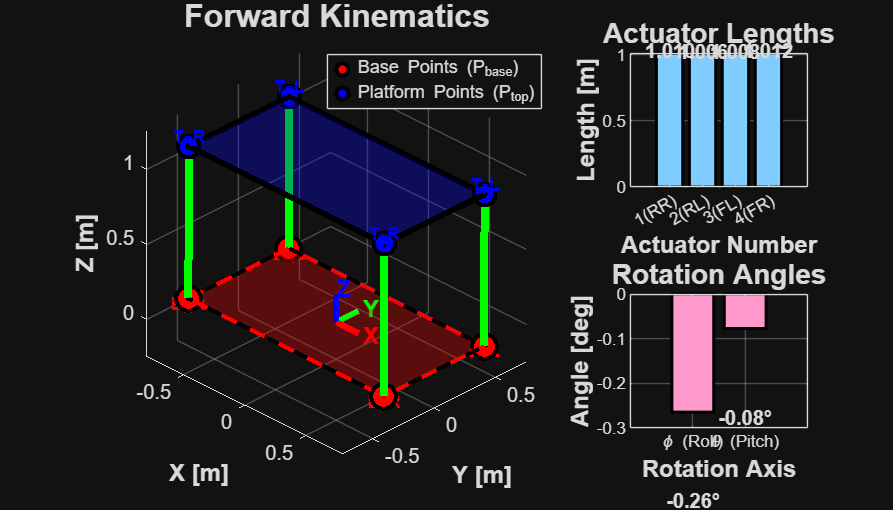

plot_stewart_fk(P_base, P_top, hrr, hrl, hfl, double(sol.hmp_fr), ...
                double(sol.phi_mp), double(sol.theta_mp))

## **Inverse Kinematics**

sol_inv = solve(eqs, [hmp_fr hmp_rr hmp_rl hmp_fl x_mp y_mp  x_fr y_fr x_fl y_fl x_rl y_rl]);
disp(sol_inv);

    hmp_fr: z_mp - (4*theta_mp)/5 - (41*phi_mp)/100
    hmp_rr: (4*theta_mp)/5 - (41*phi_mp)/100 + z_mp
    hmp_rl: (41*phi_mp)/100 + (4*theta_mp)/5 + z_mp
    hmp_fl: (41*phi_mp)/100 - (4*theta_mp)/5 + z_mp
      x_mp: (theta_mp*(80*theta_mp - 41*phi_mp + 100*z_mp))/100
      y_mp: (41*phi_mp^2)/100 - z_mp*phi_mp
      x_fr: (8*theta_mp^2)/5 + 4/5
      y_fr: -41/100
      x_fl: (8*theta_mp^2)/5 - (41*phi_mp*theta_mp)/50 + 4/5
      y_fl: (41*phi_mp^2)/50 + 41/100
      x_rl: - (41*phi_mp*theta_mp)/50 - 4/5
      y_rl: (41*phi_mp^2)/50 + 41/100



eqs_sub = subs(eqs, [phi_mp theta_mp z_mp], [sol.phi_mp sol.theta_mp sol.z_mp]);
sol_inv = solve(eqs_sub, [hmp_fr hmp_rr hmp_rl hmp_fl x_mp y_mp  x_fr y_fr x_fl y_fl x_rl y_rl]);

## Plotting

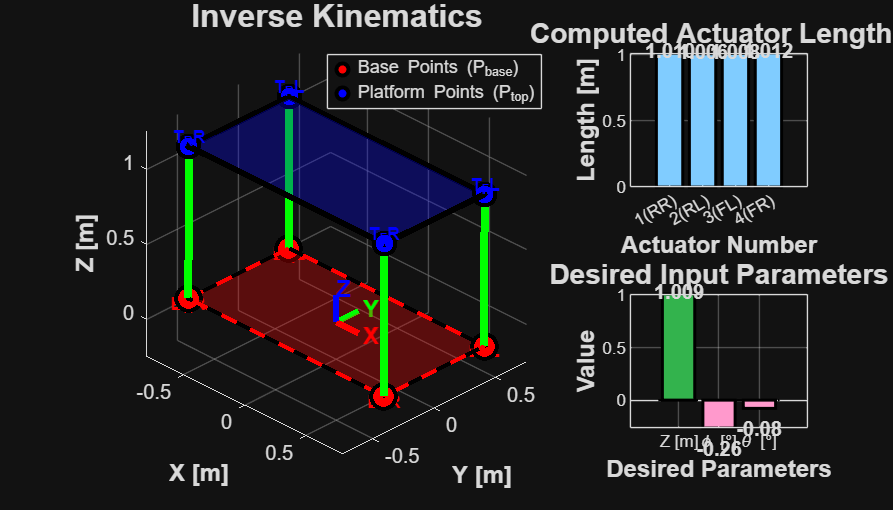

plot_stewart_ik(P_base, P_top, sol_inv, sol);

## **Motion ranges**

thaey are found considering the combinationation of maximum and minumum lenght of the actuators which produce the gradest displacment in z, phi,thetha.

Per determinare i range assunti dalle tre variabili nel sistema mobile valuto che valori assumono per Lmax e Lmin e stabilisco quindi un intervallo. Nella definizione di tutte e 4 le lunghezze i tre gradi di libertà compaiono separati e per piccoli angoli l'equazione di ogni lunghezza è lineare nelle tre variabili: Per tutto questo vale il principio di sovrapposizione delle variabili, per cui il comportamento complessivo del sistema è dato dalla somma dei comportamenti singoli, variando un solo grado di libertà alla volta e assumendo gli altri due costanti. Perchè non abbiano alcun impatto sul grado di libertà restante assumo due gradi su tre nulli

h__mp0 = 0.1896;
stroke = 0.1;
Lmax=h__mp0+stroke/2; 
Lmin=h__mp0-stroke/2; 

max_height = double(subs(z_sol, [ hmp_rr hmp_rl hmp_fl hmp_fr], [Lmax Lmax Lmax Lmax]));
min_height = double(subs(z_sol, [ hmp_rr hmp_rl hmp_fl hmp_fr], [Lmin Lmin Lmin Lmin]));


eqs_sub= subs(eqs, [ hmp_rr hmp_rl hmp_fl  hmp_fr phi_mp], [Lmax Lmax Lmin Lmin 0]);
sol = solve(eqs_sub, [x_mp y_mp z_mp theta_mp x_fr y_fr x_fl y_fl x_rl y_rl]);
theta_var = double(sol.theta_mp*180/pi);
range_theta = 2 * theta_var;

eqs_sub= subs(eqs, [ hmp_rr hmp_rl hmp_fl  hmp_fr theta_mp], [Lmax Lmin Lmin Lmax 0]);
sol = solve(eqs_sub, [x_mp y_mp z_mp phi_mp x_fr y_fr x_fl y_fl x_rl y_rl]);
phi_var = double(sol.phi_mp*180/pi);
range_phi = 2 * phi_var;

## Plotting

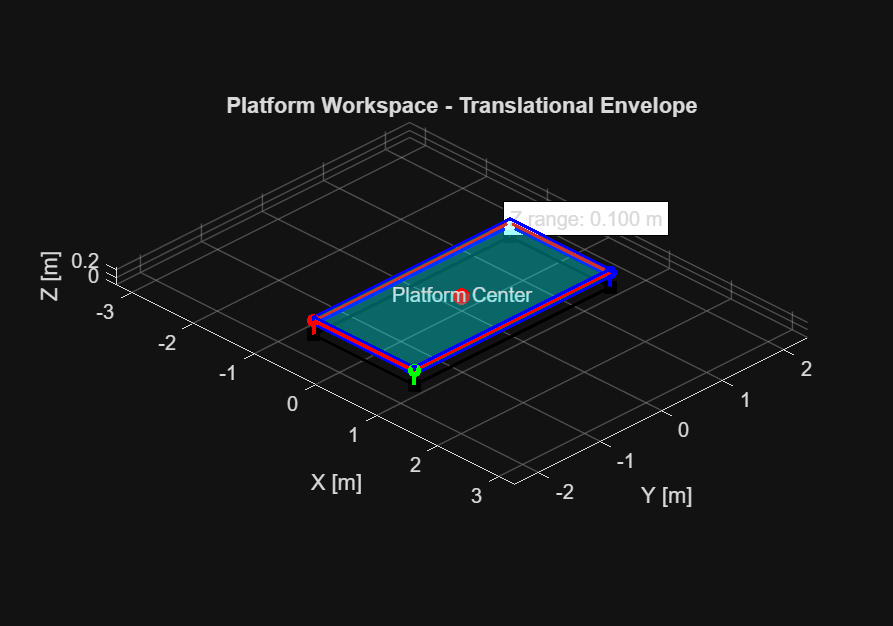

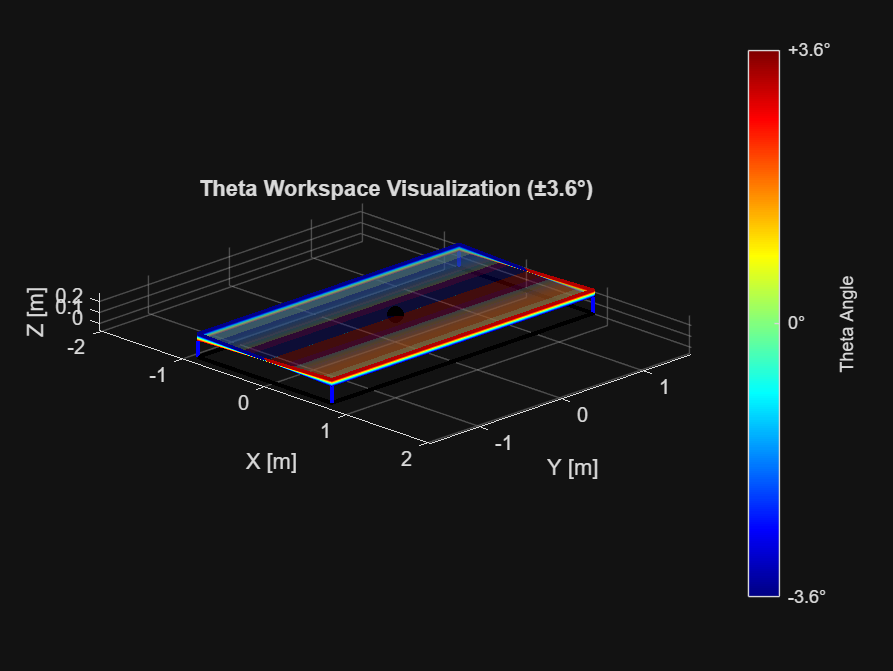

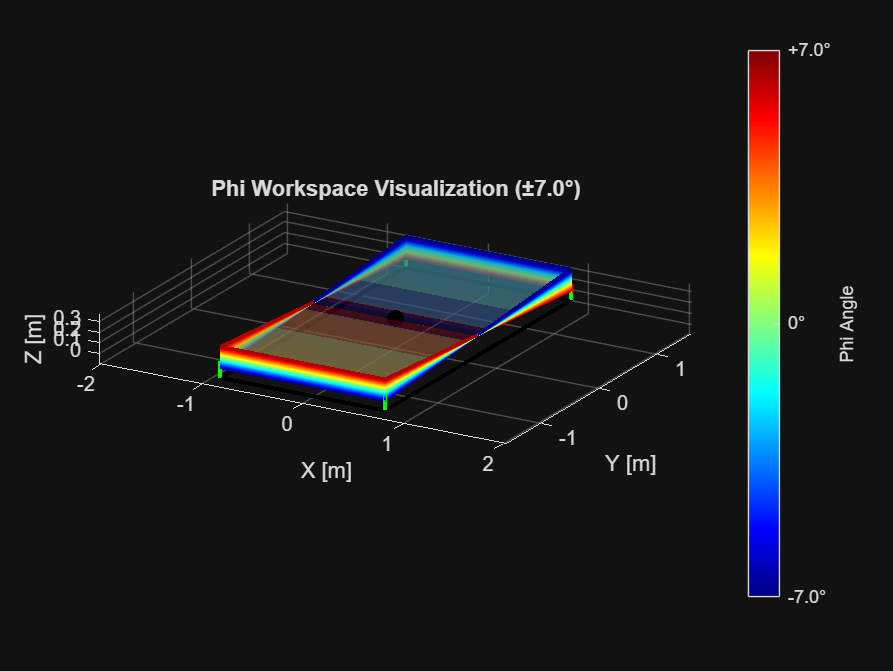

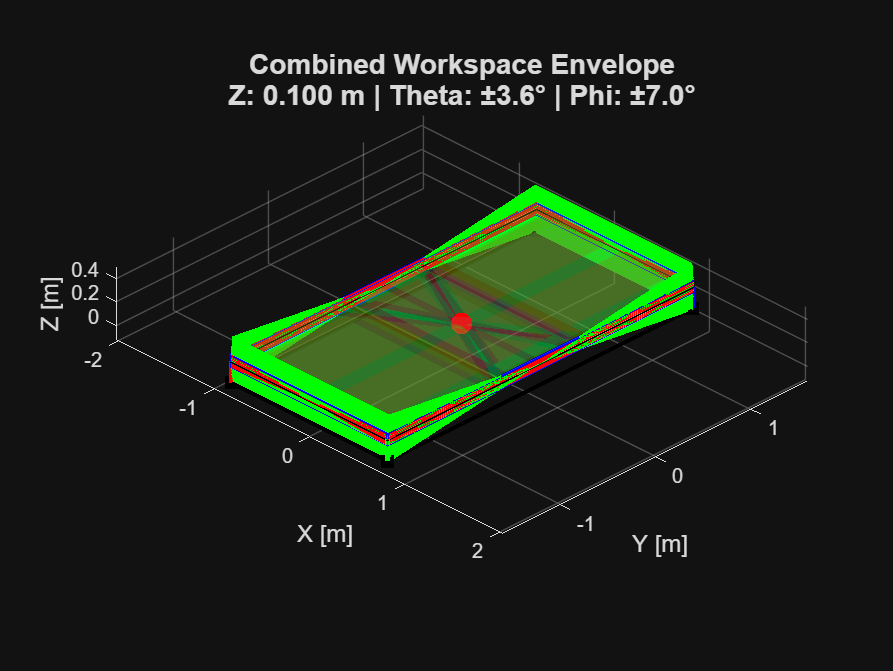

workspace(max_height, min_height, range_theta, range_phi);

So the ranges are:

$z \in [-50, 50]\ mm$

$\theta \in [3.581\ ;\ 3.581]\ degree $

$\phi \in [-6.9873\ ;\ 6.9873]\ degree$

Ho la conferma che tutte le assunzioni fatte per piccoli angoli sono valide. Questi sono i range che ha ogni grado di libertà max e min se gli altri non sono attivi. Ovviamente se gli altri gradi di libertà hanno un valore non nullo gli intervalli di valori assumibili per ogni grado di libertà si restringono.

## **Pilot**

express the pilot position as a vector in the world frame and find his velocity and accelleration.

I consider the driver as a rigid body, unable to move autonomously in space except as an indirect effect of the movement of the plate on which it rests.

syms xp yp zp
syms phi_mp(t) theta_mp(t) x_mp(t) y_mp(t) z_mp(t)

g = 9.81; 
Tmp_t = subs(Tmp,{ phi_mp theta_mp x_mp y_mp z_mp},{phi_mp(t) theta_mp(t) x_mp(t) y_mp(t) z_mp(t)});
Tpilot = Tmp_t* translate([xp yp zp]);
rbp = project(subtract(P0,get_origin(Tpilot)), TG);
disp(rbp.coords);

$$\left(\begin{array}{c} \mathrm{xp}+x_{\mathrm{mp}}\left(t\right)+\mathrm{zp}\,\theta_{\mathrm{mp}}\left(t\right)\\ \mathrm{yp}+y_{\mathrm{mp}}\left(t\right)-\mathrm{zp}\,\varphi_{\mathrm{mp}}\left(t\right)+\mathrm{xp}\,\varphi_{\mathrm{mp}}\left(t\right)\,\theta_{\mathrm{mp}}\left(t\right)\\ \mathrm{zp}+z_{\mathrm{mp}}\left(t\right)+\mathrm{yp}\,\varphi_{\mathrm{mp}}\left(t\right)-\mathrm{xp}\,\theta_{\mathrm{mp}}\left(t\right)\\ 0 \end{array}\right)$$

VG = velocity(rbp);
disp(VG.coords);

$$\left(\begin{array}{c} \mathrm{zp}\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)+\frac{\partial }{\partial t}x_{\mathrm{mp}}\left(t\right)\\ \frac{\partial }{\partial t}y_{\mathrm{mp}}\left(t\right)-\mathrm{zp}\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)+\mathrm{xp}\,\varphi_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)+\mathrm{xp}\,\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ \mathrm{yp}\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)-\mathrm{xp}\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)+\frac{\partial }{\partial t}z_{\mathrm{mp}}\left(t\right)\\ 0 \end{array}\right)$$

AG = add(velocity(VG),make_VECTOR(TG,[0 0 -g]));
disp(AG.coords);

$$\begin{array}{l} \left(\begin{array}{c} \mathrm{zp}\,\sigma_{1}+\frac{\partial^{2}}{\partial t^{2}}x_{\mathrm{mp}}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y_{\mathrm{mp}}\left(t\right)-\mathrm{zp}\,\sigma_{2}+2\,\mathrm{xp}\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)+\mathrm{xp}\,\varphi_{\mathrm{mp}}\left(t\right)\,\sigma_{1}+\mathrm{xp}\,\theta_{\mathrm{mp}}\left(t\right)\,\sigma_{2}\\ \mathrm{yp}\,\sigma_{2}-\mathrm{xp}\,\sigma_{1}+\frac{\partial^{2}}{\partial t^{2}}z_{\mathrm{mp}}\left(t\right)-\frac{981}{100}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta_{\mathrm{mp}}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\varphi_{\mathrm{mp}}\left(t\right) \end{array}$$


[SOmega_p,omega_p] = angular_velocity(Tpilot);
disp('pilot velocity');

pilot velocity


disp(omega_p.coords(1:3));

$$\left(\begin{array}{c} \frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)-\varphi_{\mathrm{mp}}\left(t\right)\,\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ \theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right) \end{array}\right)$$


alpha_p= velocity(omega_p);
disp('pilot accelleration')

pilot accelleration


disp(simplify(alpha_p.coords(1:3)));

$$\begin{array}{l} \left(\begin{array}{c} {\theta_{\mathrm{mp}}\left(t\right)}^{2}\,\sigma_{1}+\sigma_{1}+2\,\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ \sigma_{3}-\theta_{\mathrm{mp}}\left(t\right)\,\sigma_{2}-\varphi_{\mathrm{mp}}\left(t\right)\,\theta_{\mathrm{mp}}\left(t\right)\,\sigma_{1}-\varphi_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\\ -\theta_{\mathrm{mp}}\left(t\right)\,{\varphi_{\mathrm{mp}}\left(t\right)}^{2}\,\sigma_{1}+\varphi_{\mathrm{mp}}\left(t\right)\,\sigma_{3}-2\,\theta_{\mathrm{mp}}\left(t\right)\,\varphi_{\mathrm{mp}}\left(t\right)\,\sigma_{2}-\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,{\varphi_{\mathrm{mp}}\left(t\right)}^{2}\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)+\frac{\partial }{\partial t}\theta_{\mathrm{mp}}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\varphi_{\mathrm{mp}}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\varphi_{\mathrm{mp}}\left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta_{\mathrm{mp}}\left(t\right) \end{array}$$

## **Dynamics**

for the dynamics i need to reduce the numeber of coordinates i consider becouse otherway the solver is to slow. So i also need to reduce the constraint. I select the one that are relevant for q=[ z_mp(t) phi_mp(t) theta_mp(t) hmp_rr(t) hmp_rl(t) hmp_fl(t) hmp_fr(t)] (the z and angles of the platfoem and the haiths of the actiators )i then define the movement of 3 actuators as a function of time to be able to use actuator lengths directly as inputs for the analysis part. Doing thid I'm constraining the 3 dof of the platform so now i have 0 dof

syms f_1(t) f_2(t) f_3(t) 
eqs_subset = [eqs(3);eqs(6);eqs(9);eqs(12);hmp_fr-f_1(t)== 0; hmp_rl-f_2(t)== 0;hmp_fl-f_3(t)== 0];

syms hmp_rr(t) hmp_rl(t) hmp_fl(t) hmp_fr(t)  t

q= [z_mp(t) phi_mp(t) theta_mp(t) hmp_rr(t) hmp_rl(t) hmp_fl(t) hmp_fr(t)];
eqs_t=subs(eqs_subset,{z_mp phi_mp theta_mp  hmp_rr hmp_rl hmp_fl hmp_fr},q);
disp(eqs_t)

$$\begin{array}{l} \left(\begin{array}{c} {\mathrm{hmp}}_{\mathrm{rr}}\left(t\right)+\sigma_{2}-\sigma_{1}-z_{\mathrm{mp}}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{fl}}\left(t\right)-\sigma_{2}+\sigma_{1}-z_{\mathrm{mp}}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{fr}}\left(t\right)+\sigma_{2}+\sigma_{1}-z_{\mathrm{mp}}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{rl}}\left(t\right)-\sigma_{2}-\sigma_{1}-z_{\mathrm{mp}}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{fr}}\left(t\right)-f_{1}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{rl}}\left(t\right)-f_{2}\left(t\right)=0\\ {\mathrm{hmp}}_{\mathrm{fl}}\left(t\right)-f_{3}\left(t\right)=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4\,\theta_{\mathrm{mp}}\left(t\right)}{5}\\ \sigma_{2}=\frac{41\,\varphi_{\mathrm{mp}}\left(t\right)}{100} \end{array}$$

size(eqs_t)

ans =      7     1


G_q = sym(zeros(size(eqs_t))); % Pre-allocate a symbolic array for the left-hand sides
for i = 1:numel(eqs_t)
    G_q(i) = lhs(eqs_t(i));
end


i then check the jacobian of my constraitn wrt the generalized cordinates to make sure it is not singular


% 4. Compute the Jacobian dG/dq
J_constraint = jacobian(G_q, q);

% disp('Jacobian (dG/dq):');
% disp(J_constraint)

R = rank(J_constraint);
disp(['Rank of Jacobian: ', num2str(R)]);

Rank of Jacobian: 7



num_constraints = size(G_q, 1);
num_generalized_coords = size(q.',1);

disp(['Number of constraints (M): ', num2str(num_constraints)]);

Number of constraints (M): 7


disp(['Number of generalized coordinates (N): ', num2str(num_generalized_coords)]);

Number of generalized coordinates (N): 7




if R < num_constraints
    disp('Warning: The constraints are linearly dependent (redundant) or the system is in a singular configuration.');
    disp(['Actual independent constraints: ', num2str(R)]);
else
    disp('The constraints are linearly independent in this configuration.');
end

The constraints are linearly independent in this configuration.



disp(['Number of DOF: ', num2str(num_generalized_coords- num_constraints)]);

Number of DOF: 0


as aspected using 3 more constraint to control the position of my actuators as a function of time have reduce my dof to 0. otherway if the actuators would have been controlled with a force and not by adding a constraint there will be 3 dof.

i then express then express the potential and kinematic energy as a function of my generalized coordiantes di be able to use the enrgy in the lagragian formulation

m_actuator = 30; % mass of actuator [kg]
m_platform = 150;
m_driver = 75;

%i need to express x_mp(t) y_mp(t) in function of my vector q, so i use the
%results of the kinematics
sol_new_xmp = subs(sol_sym.x_mp,{ phi_mp theta_mp z_mp},{phi_mp(t) theta_mp(t) z_mp(t)});
sol_new_ymp = subs(sol_sym.y_mp,{ phi_mp theta_mp z_mp},{phi_mp(t) theta_mp(t) z_mp(t)});


Tmp_t_new = subs(Tmp_t,[x_mp(t),y_mp(t)],[sol_new_xmp, sol_new_ymp]);

center = project(subtract(P0,get_origin(Tmp_t_new)), TG);
velocity_platform = velocity(center).coords(1:3);

Tpilot = Tmp_t_new* translate([xp yp zp]);
rbp = project(subtract(P0,get_origin(Tpilot)), TG);
velocity_driver =velocity(rbp).coords(1:3);

% translational kinetic energy of actuators
T_rr = Tmp_t_new*TPrr;

rr = project(subtract(P0, get_origin(T_rr)), TG);

for small angle i can consider the z of the actuator in the global system as the length of the actuator. I need to use this becouse the lagrangian should be function of all q. The x and y of the actuar remain function only of the center of mas of the platform becouse otherway they are function of the position of their base( which is changing) and  this would introduce other variables

rr.coords(3) = hmp_rr(t);
V_rr = velocity(rr).coords(1:3);

T_trans_actuators(1) = (1/2) * (m_actuator) * (V_rr.' * V_rr);

T_fl = Tmp_t_new*TPfl;
fl = project(subtract(P0, get_origin(T_fl)), TG);
fl.coords(3) = hmp_fl(t);

V_fl = velocity(fl).coords(1:3);

T_trans_actuators(2) = (1/2) * (m_actuator) * (V_fl.' * V_fl);

T_fr = Tmp_t_new*TPfr;
fr = project(subtract(P0, get_origin(T_fr)), TG);
fr.coords(3) = hmp_fr(t);

V_fr = velocity(fr).coords(1:3);

T_trans_actuators(3) = (1/2) * (m_actuator) * (V_fr.' * V_fr);

% T_rl = TBrl_t * THp_rl_t;
T_rl = Tmp_t_new*TPrl;

rl = project(subtract(P0, get_origin(T_rl)), TG);
rl.coords(3) = hmp_rl(t);
V_rl = velocity(rl).coords(1:3);

T_trans_actuators(4) = (1/2) * (m_actuator) * (V_rl.' * V_rl);

% translational kinetic energy of platform
T_trans_platform = (1/2) * (m_platform) * (velocity_platform.' * velocity_platform);

% translational kinetic energy of driver
T_trans_driver = (1/2) * m_driver * (velocity_driver.' * velocity_driver);

% total translational kinetic energy
T_trans_total = T_trans_platform + T_trans_driver;

for i = 1:4
    T_trans_total = T_trans_total + T_trans_actuators(i);
end
% dimensions of actuators [m]
height = 559.8 / 1000;
width = 92 / 1000;  %y
lenght = 106 / 1000; %x

% inertias of actuators [kg * m^2] % Ixy ???
Ix_actuator = (1/12) * m_actuator * (height^2 + width^2);
Iy_actuator = (1/12) * m_actuator * (height^2 + lenght^2);
Iz_actuator = (1/12) * m_actuator * (width^2 + lenght^2);

% height of platform [m]
height = 0.3;
width = Wmp;
lenght = Lmp;

% inertias of platform [kg * m^2]
Ix_platform1 = (1/12) * m_platform * (height^2 + width^2);
Iy_platform1 = (1/12) * m_platform * (height^2 + lenght^2);
Iz_platform = (1/12) * m_platform * (width^2 + lenght^2);

% distaces between actuators and platform [m]
d_x = Lmp / 2;
d_y = Wmp / 2;

% Huygens-Steiner theorem 
Ix_platform = Ix_actuator + Ix_platform1 + (m_actuator * d_x^2);
Iy_platform = Iy_actuator + Iy_platform1 + (m_actuator * d_y^2);

theta_dot = diff(theta_mp, t);
phi_dot = diff(phi_mp, t);

T_rot_platform = (1/2) * Ix_platform * phi_dot^2 + (1/2) * Iy_platform * theta_dot^2;

% T_rot_driver = (1/2) * Ix_driver * phi_dot^2 + (1/2) * Iy_driver * theta_dot^2

T_tot = T_trans_total + T_rot_platform;


% potential energy
V_platform = m_platform * g * z_mp(t);

V_actuators(1) = m_actuator * g * fl.coords(3);
V_actuators(2) = m_actuator * g * fr.coords(3);
V_actuators(3) = m_actuator * g * rr.coords(3);
V_actuators(4) = m_actuator * g * rl.coords(3);

V_driver = m_driver * g * rbp.coords(3);
V_driver=0; %%!!!!!

V_tot = V_platform + V_driver;

for i = 1:4
    V_tot = V_tot + V_actuators(i);
end


syms F_ground
Q_ext = sym(zeros(length(q), 1));
Q_ext(1) = F_ground;


L = T_tot - V_tot;

lambdas = sym('lambda', [num_constraints, 1]).';

q_dot = diff(q, t);

L_diff_q = jacobian(L, q);
L_diff_q_dot = jacobian(L, q_dot);

L_diff_q_dot_diff_t = diff(L_diff_q_dot, t);

dynamics = L_diff_q_dot_diff_t.' - L_diff_q.' + J_constraint.' * lambdas.' == 0;%Q_ext;

q_dot_dot= diff(q,t,2);
a_vars = sym('a', [num_generalized_coords, 1]).'; 
syms v1(t) v2(t) v3(t) v4(t) v5(t) v6(t) v7(t) v8(t) v9(t)
v_vars = [v1(t) v2(t) v3(t) v4(t) v5(t) v6(t) v7(t)];

dynamics =subs(dynamics, q_dot_dot, a_vars);
dynamics =subs(dynamics, q_dot, v_vars);

sol_d= solve(dynamics,a_vars)

sol_d = struct with fields:
    a1: (57006882980830765790404320693130*lambda1 + 57006882980830765790404320693130*lambda2 + 57006882980830765790404320693130*lambda3 + 57006882980830765790404320693130*lambda4 + 112318660632797167331835635564544*lambda1*phi_mp(t)^2 + 11231866063279…
    a2: -(35184372088832*(843454228895029605*lambda1 - 843454228895029605*lambda2 + 843454228895029605*lambda3 - 843454228895029605*lambda4 - 1009059266519541515250*yp + 1661828262499713024*lambda1*phi_mp(t)^2 - 1661828262499713024*lambda2*phi_mp(t)^2…
    a3: (17592186044416*(2493975262591811400*lambda1 - 2493975262591811400*lambda2 - 2493975262591811400*lambda3 + 2493975262591811400*lambda4 - 1529118582876604364625*xp + 6485183463413514240*lambda1*theta_mp(t)^2 - 6485183463413514240*lambda2*theta_…
    a4: - lambda1/30 - 981/100
    a5: - lambda4/30 - lambda6/30 - 981/100
    a6: - lambda2/30 - lambda7/30 - 981/100
    a7: - lambda3/30 - lambda5/30 - 981/100



% Ciclo per costruire e memorizzare le equazioni
for i = 1:7
    fieldName = ['a' num2str(i)];
    a_vars(i) = sol_d.(fieldName);
end

now i have the diffrential and the algebric part of the DAE

### Index Reduction and converting the model for numerical solution

To determine the index of the DAE, we compute the Jacobian of the constraint equations with respect to the Lagrange multipliers. If the Jacobian is not full-rank, the constraints cannot yet be solved for the multipliers, indicating an index greater than 1.

derivs_to_sub= [q_dot,diff(v_vars,t)];
expr_to_sub_with =[v_vars,a_vars];


J = jacobian(G_q, lambdas);
fprintf('max_rank: %d | Rank: %d | Determinant is non-zero: %s\n', ...
    size(J,1), rank(J), string(~isequal(det(J), sym(0))));

max_rank: 7 | Rank: 0 | Determinant is non-zero: false


As expected, the Jacobian is singular, confirming that the system is not of index-1. We proceed to differentiate the constraint equations once with respect to time, and substitute the known expressions for the derivatives.

#### First derivation

G_q_dt = diff(G_q, t);

G_q_dt_subs = simplify(subs(G_q_dt,derivs_to_sub,expr_to_sub_with));

J = jacobian(G_q_dt_subs, lambdas);
fprintf('max_rank: %d | Rank: %d | Determinant is non-zero: %s\n', ...
    size(J,1), rank(J), string(~isequal(det(J), sym(0))));

max_rank: 7 | Rank: 0 | Determinant is non-zero: false


**Second derivation**

G_q_dt2 = diff(G_q_dt_subs, t);

G_q_dt2_subs = simplify(subs(G_q_dt2,derivs_to_sub,expr_to_sub_with));

J = jacobian(G_q_dt2_subs, lambdas);
fprintf('max_rank: %d | Rank: %d | Determinant is non-zero: %s\n', ...
    size(J,1), rank(J), string(~isequal(det(J), sym(0))));

max_rank: 7 | Rank: 7 | Determinant is non-zero: true


This time, the Jacobian is full-rank and nonsingular. This confirms that the system has been reduced to index-1, and is now in a form suitable for numerical integration. The system is formally of index-3, as two differentiations were required.

Finally, we solve the second-derivative constraint system to obtain explicit expressions for the Lagrange multipliers.

eqns = G_q_dt2_subs==0;
S = solve(eqns,lambdas);
lambdas_sol = sym(zeros(0, num_constraints));
for i = 1:num_constraints
    fieldName = ['lambda' num2str(i)];
    lambdas_sol(i) = S.(fieldName);
end

**System Response Analysis** 

Once the system has been reduced to index-1, we can numerically integrate it using a standard ODE solver. In this case, we use a fixed-step fourth-order Runge-Kutta method (`ode4`). Before doing so, it is essential to ensure that the initial state satisfies both the position-level and velocity-level constraints, otherwise numerical errors will grow rapidly over time.

**Sinusoidal**

We difine the functions f_1,f_2,f_3 which are the actuotors lengths inputs.

h__mp0 = double(354.900/1000);
stroke= 0.025;
f_1_sub = h__mp0+stroke*sin(1*t); %  fr  top rigth
f_2_sub = h__mp0+0.001*sin(1.1*t); %  rl  base left
f_3_sub = h__mp0+0.03*sin(1*t); %  fl  top left

We begin the solution of the ODE by verifying the validity of the initial conditions.

constraint = [G_q; G_q_dt_subs];
variables = [q,v_vars];

%needed to find intial velocities
syms v1 v2 v3 v4 v5 v6 v7
solution = solve(subs(G_q_dt_subs==0,v_vars,[v1 v2 v3 v4 v5 v6 v7] ),[v1 v2 v3 v4 v5 v6 v7]);
disp(solution)

    v1: diff(f_1(t), t)/2 + diff(f_2(t), t)/2
    v2: (50*diff(f_3(t), t))/41 - (50*diff(f_1(t), t))/41
    v3: (5*diff(f_2(t), t))/8 - (5*diff(f_3(t), t))/8
    v4: diff(f_1(t), t) + diff(f_2(t), t) - diff(f_3(t), t)
    v5: diff(f_2(t), t)
    v6: diff(f_3(t), t)
    v7: diff(f_1(t), t)



v_vars_sol = sym(zeros(0, num_generalized_coords));
for i = 1:num_generalized_coords
    fieldName = ['v' num2str(i)];
    v_vars_sol(i) = solution.(fieldName);
end

v_vars_sol_sin=subs(v_vars_sol, [f_1(t),f_2(t),f_3(t)], [f_1_sub,f_2_sub,f_3_sub]);
v_vars_sol_sin= @(t_num) double(subs(v_vars_sol_sin, t, t_num));

h1=h__mp0;
h2=h__mp0;
h3=h__mp0;
%needed to declare them again becouse now they are in function of t but not
%for the h_sol z_sol ...
syms hmp_fr hmp_rl hmp_fl
hrr=subs(h_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
z=subs(z_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
thetha=subs(thetha_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
phi=subs(phi_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);

initialState = [z, phi, thetha, h1, h2, h3, hrr, v_vars_sol_sin(0)];

This check ensures that both the holonomic and hidden (velocity-level) constraints are satisfied at time zero. Failing to meet these would invalidate the results of any integration process.

#### Fixed-step integration

Next, we define the system of differential equations, substituting the previously solved expressions for the Lagrange multipliers.

velocity_eqns = a_vars.';
velocity_eqns_sub = simplify(subs(velocity_eqns,lambdas,lambdas_sol));
velocity_eqns_sub = simplify(subs(velocity_eqns_sub,[xp,yp,zp],[0.5,0.5,0.5]));


An anonymous function evaluates the symbolic expression velocity_eqns_sub by substituting numerical values for the symbolic variables in state_vars. This is necessary in order to use a numerical ODE solver.

% K_ground = 1e6; % N/m
% C_ground = 1e4;  % Ns/m
% z_velocity = v_vars(1);
% F_ground_numerical =  piecewise( z_mp(t)<= 0, 0, K_ground * z_mp(t) + C_ground * z_velocity);
% velocity_eqns_sub = subs(velocity_eqns_sub,F_ground,F_ground_numerical);

velocity_eqns_sub_sin = subs(velocity_eqns_sub,[f_1(t),f_2(t),f_3(t)],[f_1_sub,f_2_sub,f_3_sub]);
state_vars = [q,v_vars];
velocity_eqns_fun_sin = @(t_numerical,y) double(subs(velocity_eqns_sub_sin, [state_vars,t], [y(:).',t_numerical]));
% velocity_eqns_fun = @(y) double(subs(velocity_eqns_sub, state_vars, y(:).'));

We then build the full right-hand side of the system. This includes the derivatives of the position variables and the computed accelerations.

daeFun = @(t, y) [
    y(8);   % dz/dt
    y(9);   % dphi/dt
    y(10);   % dthetha/dt
    y(11);   % dhrr/dt
    y(12);   % dhrl/dt
    y(13);   % dhfl/dt
    y(14);   % dhfr/dt
    velocity_eqns_fun_sin(t,y)
];

% daeFun = @(t, y) [
%     y(8);   % dz/dt
%     y(9);   % dphi/dt
%     y(10);   % dthetha/dt
%     y(11);   % dhrr/dt
%     y(12);   % dhrl/dt
%     y(13);   % dhfl/dt
%     y(14);   % dhfr/dt
%     velocity_eqns_fun(y)
% ];

Now we configure the fixed-step simulation parameters and execute the integration.

simParams.t_start = 0;   % Initial time
simParams.t_end = 10;    % Final time
simParams.h = 0.01;      % Fixed step size (critical for comparison)
simParams.tspan = simParams.t_start:simParams.h:simParams.t_end;

%state = ode4(daeFun,simParams.t_start, simParams.h , simParams.t_end, initialState);
[time,state] = ode45(daeFun, simParams.tspan, double(initialState));

This completes the time evolution of the index-1 DAE system using a fixed step-size, which allows us to observe constraint drift and integration quality.

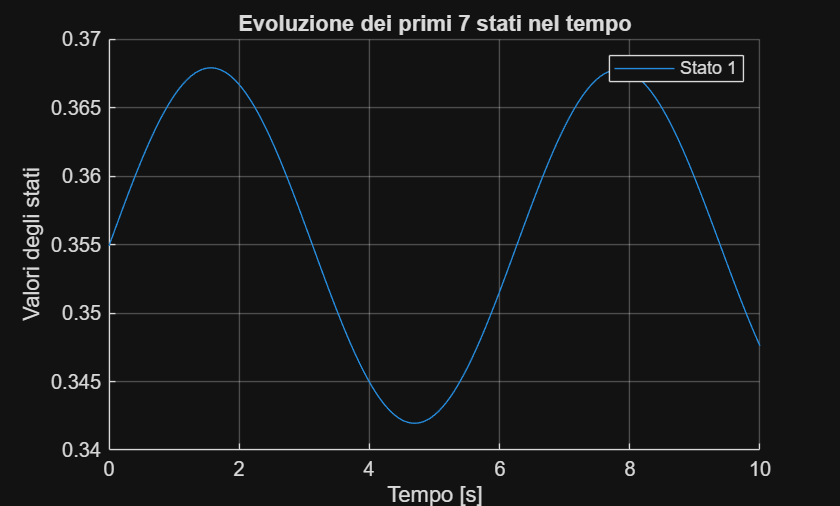

figure;
hold on;

numStates = min(1, size(state, 2));
for i = 1:numStates
    plot(simParams.tspan, state(:, i), 'DisplayName', ['Stato ' num2str(i)]);
end

xlabel('Tempo [s]');
ylabel('Valori degli stati');
legend show;
title('Evoluzione dei primi 7 stati nel tempo');
grid on;

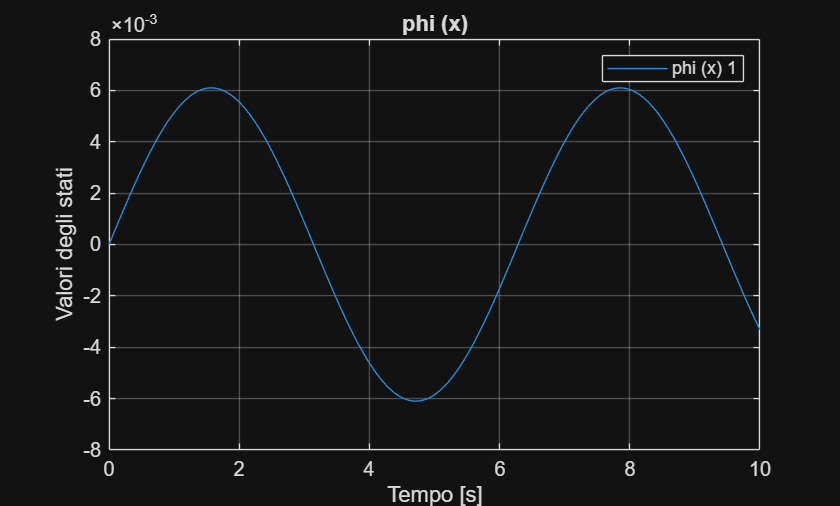


figure;

numStates = min(2, size(state, 2));  %phi
plot(simParams.tspan, state(:, numStates), 'DisplayName', ['phi (x) ' num2str(i)]);
xlabel('Tempo [s]');
ylabel('Valori degli stati');
legend show;
title('phi (x)');
grid on;

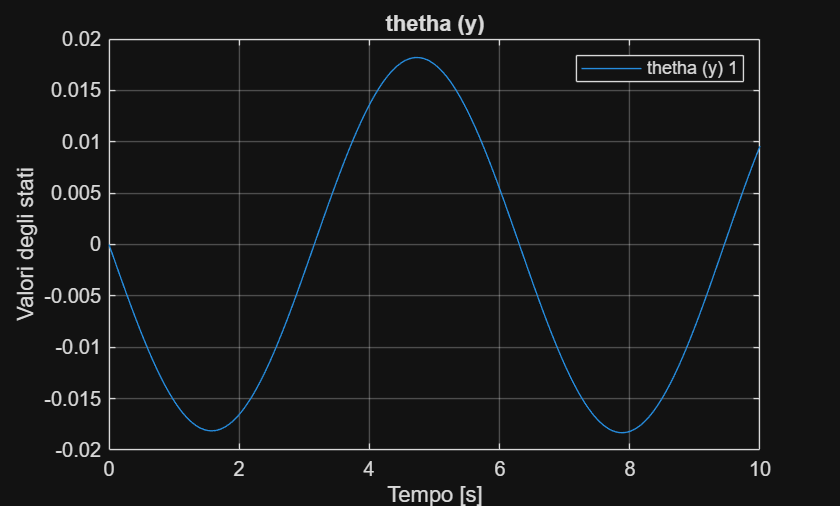


numStates = min(3, size(state, 2));  %phi
plot(simParams.tspan, state(:, numStates), 'DisplayName', ['thetha (y) ' num2str(i)]);
xlabel('Tempo [s]');
ylabel('Valori degli stati');
legend show;
title('thetha (y)');
grid on;

force on the actuators

% lambdas_sol(5)=simplify(subs(lambdas_sol(5),[xp,yp,zp],[0.5,0.5,0.5]))
% lambdas_sol(5)=subs(lambdas_sol(5),[f_1(t),f_2(t),f_3(t)],[f_1_sub,f_2_sub,f_3_sub]);
% disp(lambdas_sol(5));


**Impulse**

We difine the functions f_1,f_2,f_3 which are the actuotors lengths inputs.

k = 5;       % Pendenza
t0 = 1;      % Centro della rampa

f_1_sub = 1 ./ (1 + exp(-k * (t - t0)));
f_2_sub = 1 ./ (1 + exp(-k * (t - t0)));
f_3_sub = 1 ./ (1 + exp(-k * (t - t0)));

We begin the solution of the ODE by verifying the validity of the initial conditions.

v_vars_sol_imp=subs(v_vars_sol, [f_1(t),f_2(t),f_3(t)], [f_1_sub,f_2_sub,f_3_sub]);
v_vars_sol_imp= @(t_num) double(subs(v_vars_sol_imp, t, t_num));

h1=h__mp0;
h2=h__mp0;
h3=h__mp0;
%needed to declare them again becouse now they are in function of t but not
%for the h_sol z_sol ...
syms hmp_fr hmp_rl hmp_fl
hrr=subs(h_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
z=subs(z_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
thetha=subs(thetha_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);
phi=subs(phi_sol,[hmp_fr hmp_rl hmp_fl],[h1 h2 h3]);

initialState = [z, phi, thetha, h1, h2, h3, hrr, v_vars_sol_imp(0)];

This check ensures that both the holonomic and hidden (velocity-level) constraints are satisfied at time zero. Failing to meet these would invalidate the results of any integration process.

#### Fixed-step integration

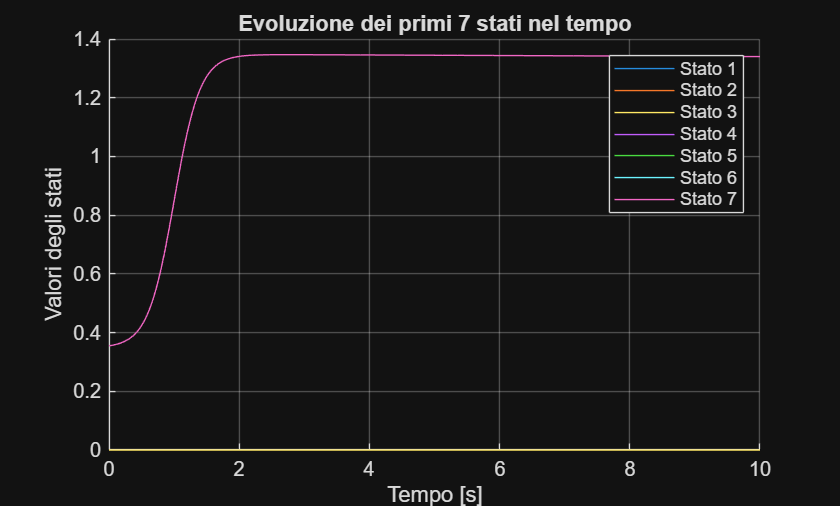

velocity_eqns_sub_imp = subs(velocity_eqns_sub,[f_1(t),f_2(t),f_3(t)],[f_1_sub,f_2_sub,f_3_sub]);
velocity_eqns_fun_imp = @(t_numerical,y) double(subs(velocity_eqns_sub_imp, [state_vars,t], [y(:).',t_numerical]));

daeFun = @(t, y) [
    y(8);   % dz/dt
    y(9);   % dphi/dt
    y(10);   % dthetha/dt
    y(11);   % dhrr/dt
    y(12);   % dhrl/dt
    y(13);   % dhfl/dt
    y(14);   % dhfr/dt
    velocity_eqns_fun_imp(t,y)
];

[time1,state1] = ode45(daeFun, simParams.tspan, double(initialState));
figure;
hold on;

numStates = min(7, size(state1, 2));
for i = 1:numStates
    plot(simParams.tspan, state1(:, i), 'DisplayName', ['Stato ' num2str(i)]);
end

xlabel('Tempo [s]');
ylabel('Valori degli stati');
legend show;
title('Evoluzione dei primi 7 stati nel tempo');
grid on;

## Simulink Model

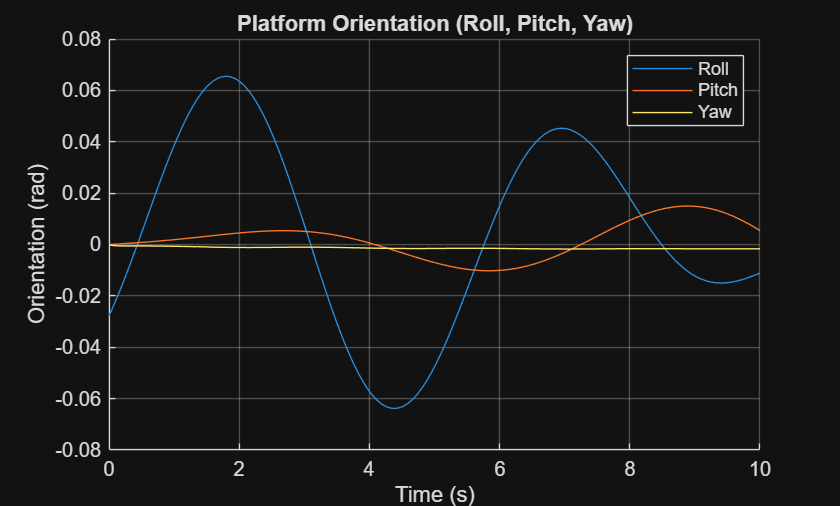

run('utilities.mlx');
model_name = 'model';
load_system(model_name);

set_param(model_name, 'StopTime', '10');
set_param(model_name, 'SaveOutput', 'on');
set_param(model_name, 'OutputSaveName', 'yout');
set_param(model_name, 'SaveTime', 'on');
set_param(model_name, 'TimeSaveName', 'tout');

simOut = sim(model_name);

platform_orientation = simOut.platform_orientation;
platform_z_position = simOut.platform_z_position;

ts = platform_orientation;

data = squeeze(ts.Data);          
data = permute(data, [2, 1]);    

figure;
hold on;

plot(ts.Time, data)
title('Platform Orientation (Roll, Pitch, Yaw)')
xlabel('Time (s)')
ylabel('Orientation (rad)')
legend('Roll','Pitch','Yaw')
grid on

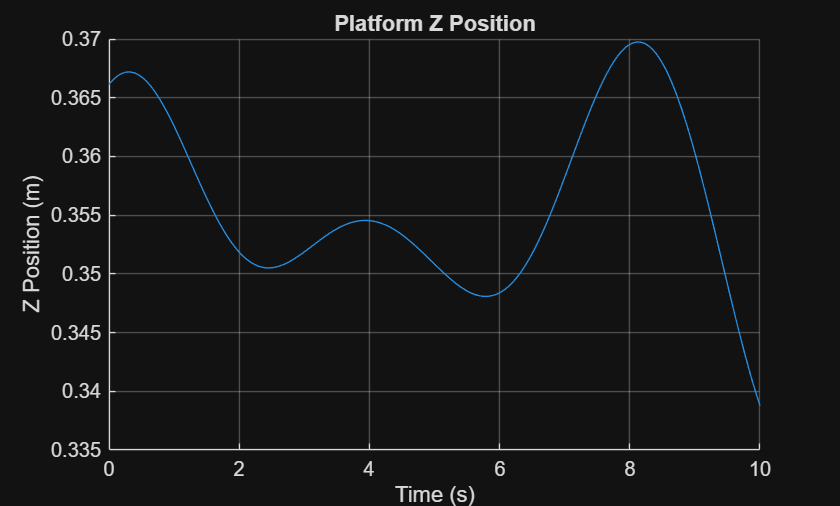


ts = platform_z_position;

data = squeeze(ts.Data);          
data = permute(data, [2, 1]);    

figure;
hold on;

plot(platform_z_position.Time, platform_z_position.Data)
title('Platform Z Position')
xlabel('Time (s)')
ylabel('Z Position (m)')
grid on